y = [1000,1000,1000,1500,2000,2000,2000,1500,1000]/1000;
x = [1000,3000,5000,5000,5000,3000,1000,1000,1000]/1000;


x_wpl = [x(1)];
y_wpl = [y(1)];
for i=2:length(x)-1
    phi1 = atan2(y(i)-y(i-1),x(i)-x(i-1));
    phi2 = atan2(y(i+1)-y(i),x(i+1)-x(i));
    if phi1 ~= phi2
        x_wpl = [x_wpl, x(i)];
        y_wpl = [y_wpl, y(i)];
    end
end
x_wpl = [x_wpl, x(length(x))]

x_wpl =      1     5     5     1     1


y_wpl = [y_wpl, y(length(y))]

y_wpl =      1     1     2     2     1


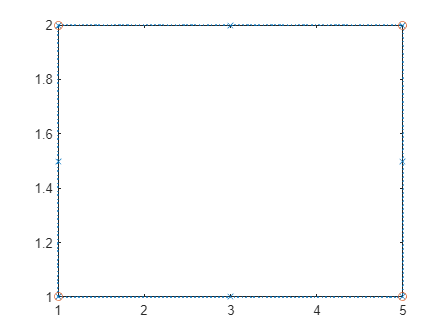


figure()
plot(x,y, "x:");
hold on;
plot(x_wpl, y_wpl, "o")


path = Path(x,y,0.4);

x =      1     5     5     1     1


y =      1     1     2     2     1


Unable to perform assignment because value of type 'BezierCurve' is not convertible to 'Spline'.

Error in Path (line 18)
               subsplines(i) = BezierCurve(x(i/2:i/2+2),y(i/2:i/2+2),r);

Caused by:
    Error using Spline
    Too many input arguments.

len = path.length
s = [0:0.01:len];
[x,y, phi] = path.getPoint(s);
[x1,y1, phi1] = path.diff(s);
[x2,y2, phi2] = path.diff(s,2);
%[kx, ky] = path.getMaxSegmentCurvature(s)


figure();
plot(x,y)
figure();
%plot(s,x1, ":x");
hold on
%plot(s,y1, ":x");
plot(s, abs(y1),":x")
plot(s, abs(x1),":x")
grid minor

%figure()
%plot(s, atan2d(y1,x1))


planner = TrajectoryPlannerSimple(path, 0.4,0.5,100,100);
planner = planner.generateTrajectory(0.05);

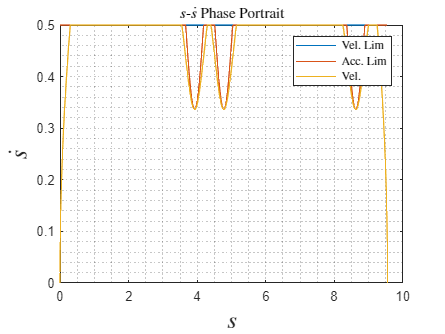

figure()
planner.plotVelLimPhasePlane(true)

[x, y]  = path.getPoint(planner.pos)

x =     1.0000
    1.0000
    1.0010
    1.0030
    1.0060
    1.0100
    1.0150
    1.0210
    1.0280
    1.0360


y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


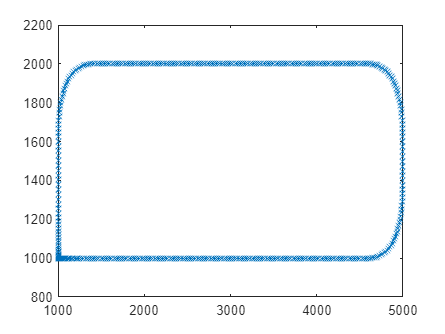

[dx,dy] = path.diff(planner.pos);
x = x*1000;
y = y*1000;

figure();
plot(x, y, ":x");

dataPath = "E:\hawino\Measurements\Trajectory\Rectangle_P3_vRef500.csv"

dataPath = "E:\hawino\Measurements\Trajectory\Rectangle_P3_vRef500.csv"

data = readtable(dataPath)

data = 2178×9 table
    Name     x_YX      x_YY     xRef_YRefX    xRef_YRefY    xObs_YObsX    xObs_YObsY    vYworldToSimulink    vXworldToSimulink
    ____    ______    ______    __________    __________    __________    __________    _________________    _________________

    NaN         10        10         10            10             10            10                10                   10     
    NaN        NaN       NaN        NaN           NaN            NaN           NaN               NaN                  NaN     
    NaN        NaN       NaN        NaN           NaN            NaN           NaN               NaN                  NaN     
    NaN        NaN       NaN        Na

vx = table2array(data(:,"vXworldToSimulink"))/1000

vx =     0.0100
       NaN
       NaN
       NaN
    0.8510
    0.0207
   -0.0125
   -0.0156
    0.0081
    0.0018


vy = table2array(data(:,"vYworldToSimulink"))/1000

vy =     0.0100
       NaN
       NaN
       NaN
    0.8510
   -0.0118
   -0.0294
   -0.0177
   -0.0264
   -0.0173


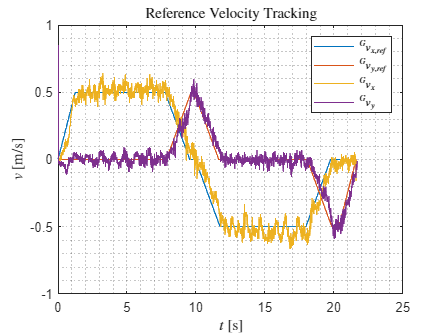


figure();
t     = [0:length(planner.pos)-1]*0.05;
tmeas = [0:5*length(t)-1]*0.01;
plot(t,dx.*planner.vel);
hold on;
grid minor;
plot(t,dy.*planner.vel);
plot(tmeas,vx(1:length(tmeas)));
plot(tmeas,vy(1:length(tmeas)));

title("Reference Velocity Tracking","interpreter","latex")
xlabel("$t$ [s]","interpreter","latex")
ylabel("$v$ [m/s]","interpreter","latex")

legend(["$^Gv_{x,ref}$","$^Gv_{y,ref}$","$^Gv_x$","$^Gv_y$"],"interpreter","latex")

#### **Switching Points**

%VII. A. 1) Caused by Acceleration Constraints and Discontinuous
s = [0:0.001:path.length] 
tol = 0.04;
idx = find((abs(diff(velMaxAcc)) > tol) == 1, 1,"first")
sp = s(idx+2);
sm = s(idx);

[~, dvelMaxP, velMaxAccP]     = planner.velMax([s(idx+1), sp])
[~, dvelMaxM, velMacAccM]     = planner.velMax([sm ,s(idx+1)])
[~, accMaxP]                  = planner.accLim(sp, velMaxAccP)
[~, accMaxM]                  = planner.accLim(sm, velMacAccM)

dvelMaxAccP = diff(velMaxAccP)./diff([s(idx+1), sp])
dvelMacAccM = diff(velMacAccM)./diff([sm ,s(idx+1)])

velMaxAccP = velMaxAccP(2);
velMacAccM = velMacAccM(1);

foundSwitchingPoint = ((velMacAccM < velMaxAccP) & (accMaxM >= dvelMacAccM)) | ((velMacAccM > velMaxAccP) & (accMaxP <= dvelMaxAccP))
ssw = s(idx+1)

%VII. A. 2) Caused by Acceleration Constraints and Continuous and Nondifferentiable

idxY = find(diff(sign(dfy(s, path))) ~= 0, 1, "first") 
idxX = find(diff(sign(dfx(s, path))) ~= 0, 1, "first") 

if ~isempty(idxY) 
    sy = fzero(@(s)dfy(s,path), [s(idxY-10) s(idxY+10)])
    foundSwitchingPoint = length(sy) ~= 0
end

if length(idxX) ~= 0
    sx = fzero(@(s)dfx(s,path), [s(idxX-10) s(idxX+10)])
    foundSwitchingPoint = length(sx) ~= 0
end


%VII. A. 2) B. Caused by Velocity Constraints and Continuous
% idx = find(diff(sign(swPointContVel(s,planner))) ~= 0) 
% s(idx+1)
% foundSwitchingPoint = length(s(idx+1)) ~= 0
figure()


%VII. A. 2) B. Caused by Velocity Constraints and Discontinuous
[ddx, ddy] = path.diff(s, 2);
tol = 0.3;
idx = find((abs(diff(ddx)) > tol) == 1, 1,"first")

[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))

idx = find((abs(diff(ddy)) > tol) == 1, 1,"first")
[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))


## Backward Integration crossing point search

x1 = [[0:0.01:4],zeros(1,1000) ]
y1 = x1.^2;

x2 =[4.5:-0.0133:2];
y2 = (x2-4.5).^2;

figure();
plot(x1, y1,":x")
hold on
plot(x2, y2,":x")

for i = 1:length(x2)
    idx1 = find(x2(i) < x1, 1, "first");
    if(y2(i) > y1(idx1))
        idx2 = i;
        break;
    end
end
length(y1)
x1(idx1:idx1+idx2-2) = flip(x2(1:idx2-1))
y1(idx1:idx1+idx2-2) = flip(y2(1:idx2-1))
figure()
plot(x1,y1,"--x")

function swPointContVel = swPointContVel(s, planner)
        [valMax, ~, velMaxAcc] = planner.velMax(s);
        [accMin, ~]  = planner.accLim(s, valMax);
        dvelMaxAcc  =diff([0; velMaxAcc]);
        swPointContVel  = accMin -dvelMaxAcc;       
end

function ret = dvelMaxAccFunc(s, planner)
      ds  = 1e-6;
     [~, ~, velMaxAcc] = planner.velMax([s-ds, s+ds]);
     ret = diff(velMaxAcc)/(2*ds);
end